# WorkSheet 5

### Problem 1

% Setting up the intial value conditons 
f = @(t) exp(t).*sin(16.*t);
t0 = 0;
tf = 5;
y0 = 1;

% Part a
nsteps = 10;
t_1a = linspace(t0,tf,nsteps+1)';
ans_1a = forward_euler(t0,tf,y0,f,nsteps)

ans_1a =     1.0000
    1.8156
    1.4243
   -0.6050
    1.4323
    5.9710
   -1.7444
  -10.3801
   14.7357
   26.1599



% Part b
nsteps = 30;
t_1b = linspace(t0,tf,nsteps+1)';
ans_1b = forward_euler(t0,tf,y0,f,nsteps)

ans_1b =     1.0000
    1.0900
    0.9009
    1.1727
    0.8655
    1.1316
    1.0012
    0.9038
    1.2904
    0.6140



% Part c 
nsteps = 1000;
t_1c = linspace(t0,tf,nsteps+1)'

t_1c =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


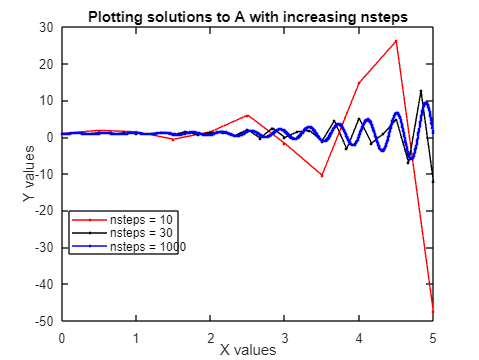

ans_1c = forward_euler(t0,tf,y0,f,nsteps);

% Part d
figure()
plot(t_1a, ans_1a, 'r.-')
hold on 
plot(t_1b, ans_1b, 'k.-')
plot(t_1c, ans_1c, 'b.-')
hold off
xlabel('X values')
ylabel('Y values')
title('Plotting solutions to A with increasing nsteps')
legend('nsteps = 10', 'nsteps = 30', 'nsteps = 1000', 'location', 'best')

### Problem 2

% Setting up the intial value conditons 
f = @(t) (1/100).*(6.*(t.^5)-10.*(t.^4)-104.*(t.^3)+84.*(t.^2)+290.*(t)-26);
t0 = -4;
tf = 5;
y0 = 0.4;

% Part a
nsteps = 20;
t_2a = linspace(t0,tf,nsteps+1)';
ans_2a = forward_euler(t0,tf,y0,f,nsteps)

ans_2a =     0.4000
   -1.0184
    0.5081
    2.5490
    3.9281
    4.3280
    3.9527
    3.2515
    2.7015
    2.6506



% Part b
nsteps = 40;
t_2b = linspace(t0,tf,nsteps+1)';
ans_2b = forward_euler(t0,tf,y0,f,nsteps)

ans_2b =     0.4000
   -1.7588
   -2.4680
   -2.2413
   -1.4780
   -0.4785
    0.5419
    1.4393
    2.1289
    2.5736



% Part c
nsteps = 80;
t_2c = linspace(t0,tf,nsteps+1)';
ans_2c = forward_euler(t0,tf,y0,f,nsteps)

ans_2c =     0.4000
   -1.1582
   -2.2376
   -2.9186
   -3.2732
   -3.3655
   -3.2521
   -2.9829
   -2.6013
   -2.1446



% Part d
nsteps = 160;
t_2d = linspace(t0,tf,nsteps+1)';
ans_2d = forward_euler(t0,tf,y0,f,nsteps)

ans_2d =     0.4000
   -0.5152
   -1.2943
   -1.9484
   -2.4881
   -2.9235
   -3.2640
   -3.5186
   -3.6960
   -3.8039



% Part e
nsteps = 320;
t_2e = linspace(t0,tf,nsteps+1)';
ans_2e = forward_euler(t0,tf,y0,f,nsteps)

ans_2e =     0.4000
   -0.0938
   -0.5515
   -0.9743
   -1.3639
   -1.7215
   -2.0485
   -2.3463
   -2.6162
   -2.8593



% Part f 
f_1 = @(t) (1/100).*((t.^6)-2.*(t.^5)-26.*(t.^4)+28.*(t.^3)+145.*(t.^2)-26.*(t)-80)

f_1 = function_handle with value:
    @(t)(1/100).*((t.^6)-2.*(t.^5)-26.*(t.^4)+28.*(t.^3)+145.*(t.^2)-26.*(t)-80)


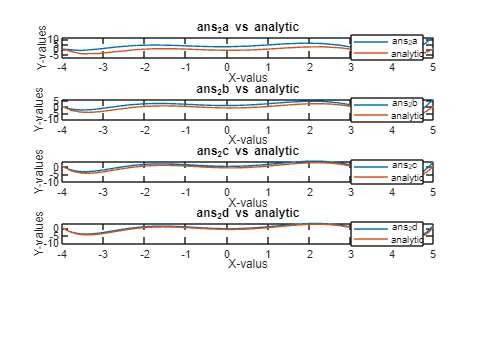


figure()
subplot(5,1,1);
plot (t_2a,ans_2a)
hold on
plot(t_2a,f_1(t_2a));
hold off
xlabel('X-valus');
ylabel('Y-values');
title('ans_2a vs analytic');
legend('ans_2a','analytic', 'location', 'best');

subplot(5,1,2);
plot (t_2b,ans_2b);
hold on
plot(t_2b,f_1(t_2b));
hold off
xlabel('X-valus');
ylabel('Y-values');
title('ans_2b vs analytic');
legend('ans_2b','analytic', 'location', 'best');


subplot(5,1,3);
plot (t_2c,ans_2c);
hold on
plot(t_2c,f_1(t_2c));
hold off
xlabel('X-valus');
ylabel('Y-values');
title('ans_2c vs analytic');
legend('ans_2c','analytic', 'location', 'best');


subplot(5,1,4);
plot (t_2d,ans_2d);
hold on
plot(t_2d,f_1(t_2d));
hold off
xlabel('X-valus');
ylabel('Y-values');
title('ans_2d vs analytic');
legend('ans_2d','analytic', 'location', 'best');

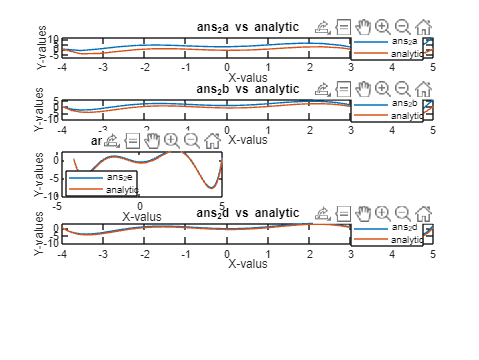


subplot(5,2,5);
plot (t_2e,ans_2e);
hold on
plot(t_2e,f_1(t_2e));
hold off
xlabel('X-valus');
ylabel('Y-values');
title('ans_2e vs analytic');
legend('ans_2e','analytic', 'location', 'best');


% Part g -- calculating and plotting the max-abs error terms
error1 = norm(ans_2a - f_1(t_2a),Inf);
error2 = norm(ans_2b - f_1(t_2b),Inf);
error3 = norm(ans_2c - f_1(t_2c),Inf);
error4 = norm(ans_2d - f_1(t_2d),Inf);
error5 = norm(ans_2e - f_1(t_2e),Inf);

Errors = [error1, error2, error3, error4, error5]

Errors =    11.4295    5.6216    2.7875    1.3879    0.6925


N_Steps = [20,40,80,160,320]

N_Steps =     20    40    80   160   320


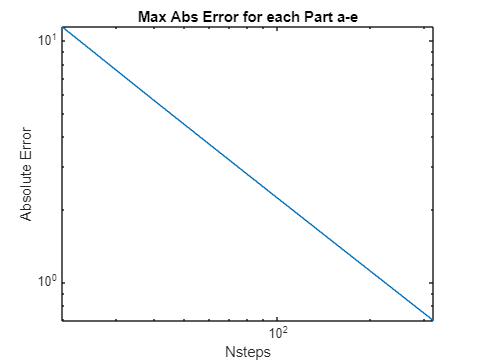


figure()
loglog(N_Steps,Errors);
xlabel('Nsteps');
ylabel('Absolute Error');
title('Max Abs Error for each Part a-e');